# Изучение движения звёзд

close all
clear variables

## Импорт данных

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

## Константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

## Определение диапазона длин волн

% нобсы - число наблюдений ( 2 пункт задания )
% 1
nObs = size(spectra, 1);
nomerStar = size(spectra, 2);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Расчет скорости удаление звезды от Земли

% 1
s = spectra;
[sHa, idx] = min(s);
lambdaHa = lambda(idx);

z = (lambdaHa / lambdaPr) - 1;
speed = z * speedOfLight;
movaway = starNames(speed > 0);

## Построение графика

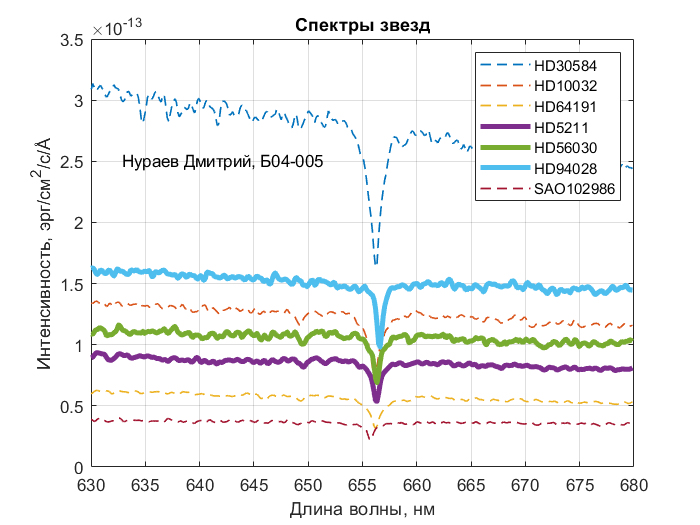

fg1 = figure;
PLT = plot(lambda, s, '--', 'LineWidth', 1);

for i = 1 : 1 : nomerStar
    if speed(i) > 0
        PLT(i).LineWidth = 3;
        PLT(i).LineStyle = '-';
    end
end

set(fg1,'Visible', 'on');
title({'Спектры звезд'})
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
grid on
text(lambdaEnd - 47, max(s(2))*0.8, 'Нураев Дмитрий, Б04-005')
legend(starNames, 'Location', 'northeast')

## Сохранение графика в PNG

saveas(fg1, 'spectragrafic.png')